# Read all the images 

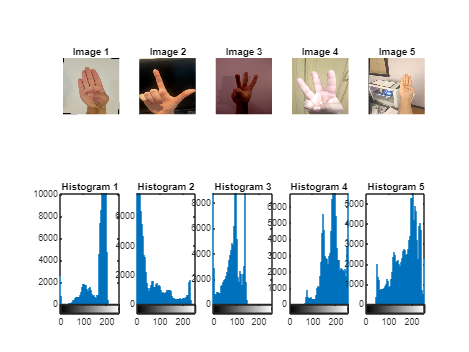

% Directory path
directory = 'Datasets\Task1\Images';
folderpath='Train';

% Get a list of all files in the directory
fileList = dir(fullfile(directory, '*.jpg'));

% Loop through the list and read each image
images = cell(1, 5); % Initialize cell array to store images
hist = cell(1, 5);
images_squared = cell(1, 5);
list=[1 ,2 ,9 ,29 ,38 ];

for i = 1:5
    % Get the file name
    fileName = fullfile(directory, fileList(list(i)).name);
    
    % Read the image
    image = imread(fileName);
    
    % Store the image in the cell array
    
    images{i} = image;
end

% Display the images like a filmstrip
figure;
subplot(2,5,1);imshow(images{1});title('Image 1');
subplot(2,5,2);imshow(images{2});title('Image 2');
subplot(2,5,3);imshow(images{3});title('Image 3');
subplot(2,5,4);imshow(images{4});title('Image 4');
subplot(2,5,5);imshow(images{5});title('Image 5');
subplot(2,5,6);imhist(images{1});title('Histogram 1');
subplot(2,5,7);imhist(images{2});title('Histogram 2');
subplot(2,5,8);imhist(images{3});title('Histogram 3');
subplot(2,5,9);imhist(images{4});title('Histogram 4');
subplot(2,5,10);imhist(images{5});title('Histogram 5');

## Equalizing Images 

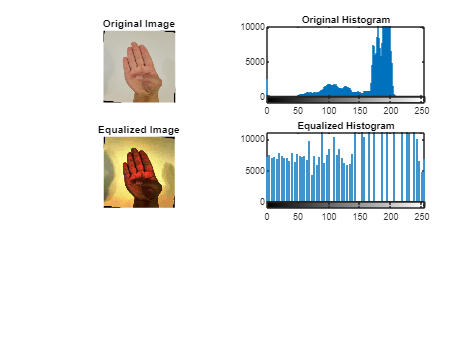

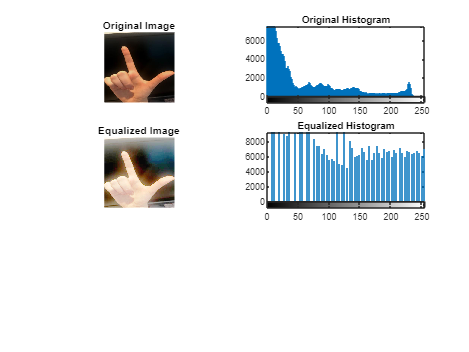

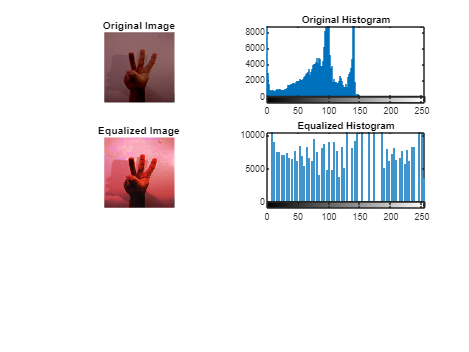

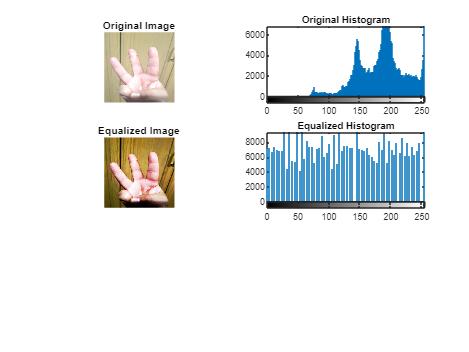

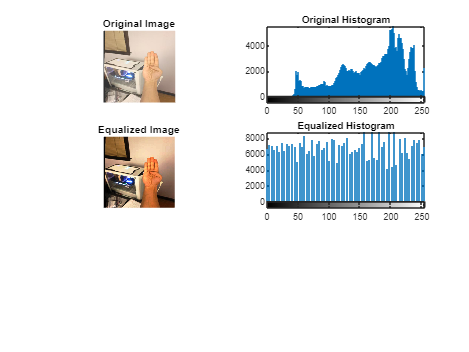

%% Equalizing Images %%

for n=1:5
    
    img=images{n};
    
    img_eq=histeq(img);
    
    %images{n}=img_eq;
    
    figure();
    subplot(3,2,1);imshow(img);title('Original Image');
    subplot(3,2,2);imhist(img);title('Original Histogram');
    subplot(3,2,3);imshow(img_eq);title('Equalized Image');
    subplot(3,2,4);imhist(img_eq);title('Equalized Histogram');

    % images{n}=imadjust(img,[0/255 255/255], [0 1],1);
    % subplot(3,2,5);imshow(images{n});title('Stretched Image');
    % subplot(3,2,6);imhist(images{n});title('Stretched Histogram');
end

## Edge Detection

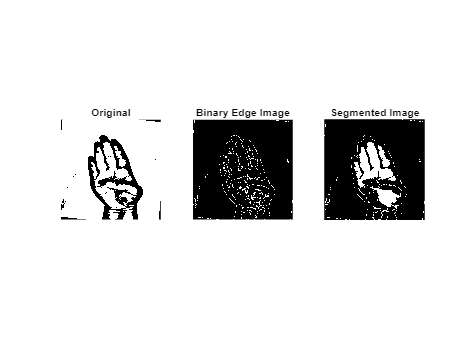

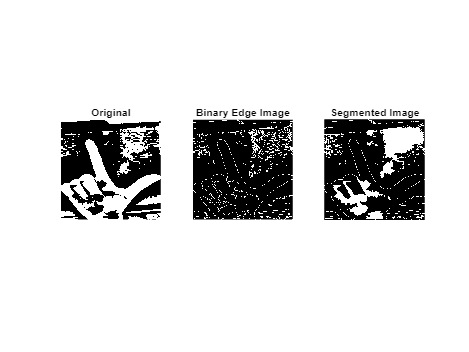

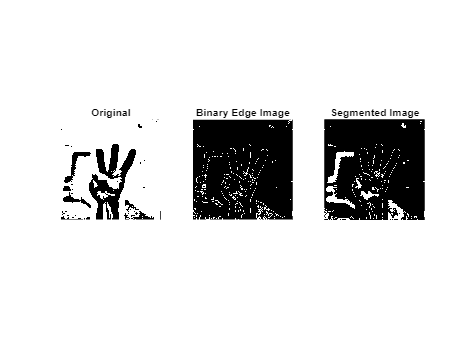

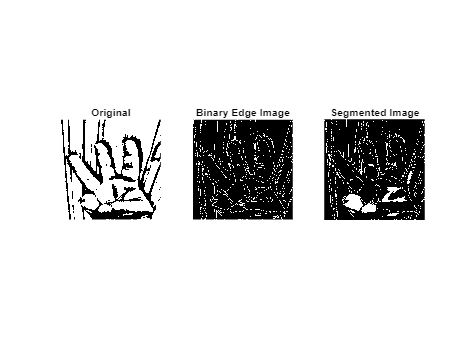

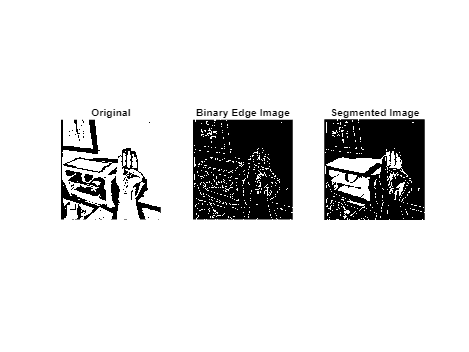

for n=1:5
    I=rgb2gray(images{n});
    I2=imbinarize(I,"adaptive","Sensitivity",0.62);

    hor=edge(I2,'sobel', 0.1,'horizontal');
    ver=edge(I2,'sobel',0.1,'vertical');
    fig_edges=hor+ver;
    fig_filled_edges=imfill(fig_edges,4,'holes');

    figure();
    subplot(1,3,1);imshow(I2), title("Original");
    subplot(1,3,2);imshow(fig_edges), title('Binary Edge Image');
    subplot(1,3,3), imshow(fig_filled_edges), title('Segmented Image');

end

## Parse the skin colour 

% for n=1:5
% 
%     img=images{n};
% 
%     R=img(:,:,1);G=img(:,:,2);B=img(:,:,3);
% 
%     figure();
%     subplot(3,1,1);imshow(R);title('Red Plane');
%     subplot(3,1,2);imshow(G);title('Green Plane');
%     subplot(3,1,3);imshow(B);title('Blue Plane');
% end

## Chatgpt

% Loop through each image
% for i = 1:5
%     % Read the image
%     img = images{i};
% 
%     % Preprocess the image (convert to appropriate color space)
%     % For example, convert RGB to YCbCr
%     imgYCbCr = rgb2ycbcr(img);
% 
%     % Extract the Y, Cb, and Cr channels
%     Y = imgYCbCr(:,:,1);
%     Cb = imgYCbCr(:,:,2);
%     Cr = imgYCbCr(:,:,3);
% 
%     % Define thresholds for skin detection in YCbCr space
%     % You may need to adjust these thresholds based on your images
%     skinMask = (Cb >= 77 & Cb <= 127) & (Cr >= 133 & Cr <= 173);
% 
%     % Perform morphological operations for refinement (optional)
%     skinMask = imopen(skinMask, strel('disk', 5));
% 
%     % Visualize the results
%     figure;
%     subplot(1, 2, 1);
%     imshow(img);
%     title('Original Image');
%     subplot(1, 2, 2);
%     imshow(skinMask);
%     title('Skin Region');
% end

